% 1. load the different ports and use their corresponding channels to get
% the pressure distribution for it. 


port1 = readmatrix("subsonic_Port01_1_0.dat"); 
port2 = readmatrix("subsonic_Port02_1_0.dat");
port3 = readmatrix("subsonic_Port03_1_0.dat");
port4 = readmatrix("subsonic_Port04_1_0.dat");
port5 = readmatrix("subsonic_Port05_1_0.dat");
port6 = readmatrix("subsonic_Port06_1_0.dat");
port7 = readmatrix("subsonic_Port07_1_0.dat");

port11 = readmatrix("supersonic_Port01_1_0.dat"); 
port12 = readmatrix("supersonic_Port02_1_0.dat");
port13 = readmatrix("supersonic_Port03_1_0.dat");
port14 = readmatrix("supersonic_Port04_1_0.dat");
port15 = readmatrix("supersonic_Port05_1_0.dat");
port16 = readmatrix("supersonic_Port06_1_0.dat");
port17 = readmatrix("supersonic_Port07_1_0.dat");
data = port5;

gain = 1.7838e4; % Pa/V

startData = readmatrix('supersonic_Port07_offset_0.dat', ...
    'FileType', 'text', 'Delimiter', '\t', ...
    'NumHeaderLines', 18);

endData = readmatrix('offset_final_Port07_0.dat', ...
    'FileType', 'text', 'Delimiter', '\t', ...
    'NumHeaderLines', 18);

startVoltage = startData(:, 2:13);
endVoltage = endData(:, 2:13);

startOffset = mean(startVoltage, 1, 'omitnan');
endOffset = mean(endVoltage, 1, 'omitnan');

channelOffset = (startOffset + endOffset) / 2;
averageOffset = mean(channelOffset);
averagepress = mean(gain*channelOffset);

time = data(:, 1);
voltage = data(:, 2:13);

% Average the 12 channels at each time sample
averageVoltage = mean(voltage, 2, 'omitnan');

correctedVoltage = averageVoltage - averageOffset;
pressure = gain * correctedVoltage;

% Mean pressure and pressure fluctuations
meanPressure = mean(pressure, 'omitnan');
pressureFluctuation = pressure - meanPressure;

fprintf('Mean pressure = %.2f Pa\n', meanPressure);

Mean pressure = -19592.98 Pa


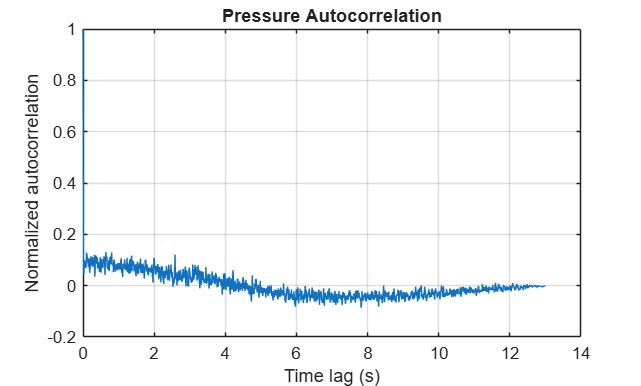


% Time between samples
dt = mean(diff(time));

% Calculate normalized autocorrelation
[Bxx, lags] = xcorr(pressureFluctuation, 'coeff');

% Keep only zero and positive time lags
positiveLags = lags >= 0;
Bxx = Bxx(positiveLags);
lags = lags(positiveLags);

% Convert lags to seconds
timeLag = lags * dt;

% Find the first zero crossing
zeroIndex = find(Bxx <= 0, 1);

% Plot autocorrelation
figure;
plot(timeLag, Bxx);
xlabel('Time lag (s)');
ylabel('Normalized autocorrelation');
title('Pressure Autocorrelation');
grid on;


% Integral time scale up to the first zero crossing
integralTime = 2*trapz(timeLag(1:zeroIndex), Bxx(1:zeroIndex));

fprintf('First zero crossing = %.5f s\n', timeLag(zeroIndex));

First zero crossing = 2.52727 s


fprintf('Integral time scale = %.5f s\n', integralTime);

Integral time scale = 0.37860 s




%to find the static pressure distribution at each port, you take the
%voltage channel for that port and then you subtract it from the offset
%voltage. Alternatively, you can take the voltage, convert it to pressure
%and subtract it by the ambient pressure. 

% Calculate mean static pressure for each port using its corresponding
% channel. 

% PORT 1: gain = 1.7838e4;   % Pa/V

% Load all 7 files into a cell array
nFiles = 7;
ports = cell(1, nFiles);
for k = 1:nFiles
    ports{k} = readmatrix(sprintf("subsonic_Port%02d_1_0.dat", k));
end

% Column in each file that corresponds to v_port1 ... v_port10
% (keeps your mapping, including the 6/5 swap for ports 4 and 5)
chan = [2 3 4 6 5 7 8 9 10 12 11];
nPorts = numel(chan);

% Sensor locations (mm). Only 10 ports are used, so the first 10 entries.
x_all = [11.6 24.7, 36.6, 48.3, 61.0, 73.7, 86.4, 99.1, 118, 209.5, 300.1];
x = x_all(1:nPorts);

% Rows = file (Port01..Port07), columns = pressure port (v_port1..v_port10)
P_each     = zeros(nFiles, nPorts);

for k = 1:nFiles
    for j = 1:nPorts
        V = ports{k}(:, chan(j));
        P_each(k, j)     = mean(gain * (V - averageOffset) + 101300, 'omitnan');
    end
end

offset_e = sqrt((std(startOffset)/7)^2 + (std(endOffset)/7)^2);
% Average and spread across the 7 files for each port
v_ports     = mean(P_each, 1);        % 1x10, offset-corrected
spread      = std(P_each, 0, 1);      % error bars, offset-corrected

stat_p_1_sub_e = gain * sqrt(offset_e^2 + (std(port1(:,2))./sqrt(7)).^2);
stat_p_2_sub_e = gain * sqrt(offset_e^2 + (std(port2(:,3))./sqrt(7)).^2);
stat_p_3_sub_e = gain * sqrt(offset_e^2 + (std(port3(:,4))./sqrt(7)).^2);
stat_p_4_sub_e = gain * sqrt(offset_e^2 + (std(port4(:,6))./sqrt(7)).^2);
stat_p_5_sub_e = gain * sqrt(offset_e^2 + (std(port5(:,5))./sqrt(7)).^2);
stat_p_6_sub_e = gain * sqrt(offset_e^2 + (std(port6(:,7))./sqrt(7)).^2);
stat_p_7_sub_e = gain * sqrt(offset_e^2 + (std(port7(:,8))./sqrt(7)).^2);
stat_p_8_sub_e = gain * sqrt(offset_e^2 + (std(port7(:,9))./sqrt(7)).^2);
stat_p_9_sub_e = gain * sqrt(offset_e^2 + (std(port7(:,10))./sqrt(7)).^2);
stat_p_10_sub_e = gain * sqrt(offset_e^2 + (std(port7(:,12))./sqrt(7)).^2);
stat_p_11_sub_e = gain * sqrt(offset_e^2 + (std(port7(:,11))./sqrt(7)).^2);

stat_p_sub_e   = [stat_p_1_sub_e, stat_p_2_sub_e, stat_p_3_sub_e, stat_p_4_sub_e, ...
    stat_p_5_sub_e, stat_p_6_sub_e, stat_p_7_sub_e, stat_p_8_sub_e, stat_p_9_sub_e, stat_p_10_sub_e, stat_p_11_sub_e];

% Static pressure distribution with error bars
% figure;
% errorbar(x, v_ports,stat_p_sub_e, '-o');
% xlabel('Position along surface (mm)');
% ylabel('Mean static pressure (Pa)');
% title('Static Pressure Subsonic Distribution');
% grid on;
% Table of results
disp(table((1:nPorts)', x', v_ports', spread', ...
    'VariableNames', {'Port','x_mm','MeanPressure_Pa','StdAcrossFiles_Pa'}));

    Port    x_mm     MeanPressure_Pa    StdAcrossFiles_Pa
    ____    _____    _______________    _________________

      1      11.6         79095              202.51      
      2      24.7         73492              498.41      
      3      36.6         73974              548.55      
      4      48.3         78486              435.73      
      5        61         82214              404.05      
      6      73.7         85240              358.57      
      7      86.4         52154              411.56      
      8      99.1         84028              316.31      
      9       118         84822              88.237      
     10     209.5         86783              68.213      
     11     300.1         94846              30.729      



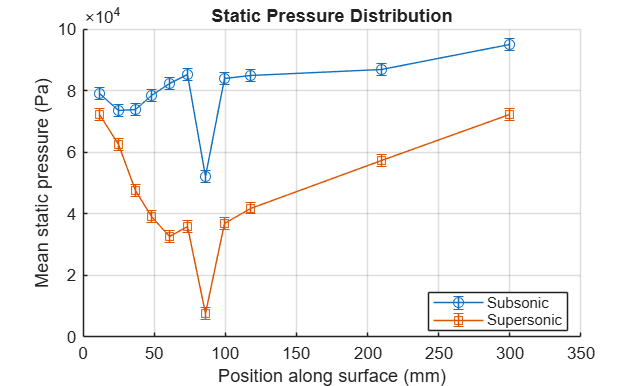


% Supersonic Data Processing

nFiles = 7;
supersonic_ports = cell(1, nFiles);

for k = 1:nFiles
    supersonic_ports{k} = readmatrix(sprintf("supersonic_Port%02d_1_0.dat", k));
end

% Channel mapping (matching your indices, including the 6/5 swap)

%V0 = col2, V1 = col3, V2 = col4, V3 = col5, V4 = col7, V5 = col6, V6 = col 8, V7 = col 9, V8 = col10, V9 = col12, V10 = col11, V11 = col13(stag_p) 
chan = [2 3 4 6 5 7 8 9 10 12 11];
nPorts = numel(chan);

% Sensor locations (mm)
x_all = [11.6 24.7, 36.6, 48.3, 61.0, 73.7, 86.4, 99.1, 118, 209.5, 300.1];
x = x_all(1:nPorts);

% Preallocate matrices for supersonic data
P_super     = zeros(nFiles, nPorts);
P_super_alt = zeros(nFiles, nPorts);

for k = 1:nFiles
    for j = 1:nPorts
        V = supersonic_ports{k}(:, chan(j));
        P_super(k, j)     = mean(gain * (V - averageOffset) + 101300, 'omitnan');
    end
end

% Average and spread across the 7 files for each port
v_supersonic       = mean(P_super, 1);
spread_super       = std(P_super, 0, 1);

stat_p_1_super_e = gain * sqrt(offset_e^2 + (std(port1(:,2))./sqrt(7)).^2);
stat_p_2_super_e = gain * sqrt(offset_e^2 + (std(port2(:,3))./sqrt(7)).^2);
stat_p_3_super_e = gain * sqrt(offset_e^2 + (std(port3(:,4))./sqrt(7)).^2);
stat_p_4_super_e = gain * sqrt(offset_e^2 + (std(port4(:,6))./sqrt(7)).^2);
stat_p_5_super_e = gain * sqrt(offset_e^2 + (std(port5(:,5))./sqrt(7)).^2);
stat_p_6_super_e = gain * sqrt(offset_e^2 + (std(port6(:,7))./sqrt(7)).^2);
stat_p_7_super_e = gain * sqrt(offset_e^2 + (std(port7(:,8))./sqrt(7)).^2);
stat_p_8_super_e = gain * sqrt(offset_e^2 + (std(port7(:,9))./sqrt(7)).^2);
stat_p_9_super_e = gain * sqrt(offset_e^2 + (std(port7(:,10))./sqrt(7)).^2);
stat_p_10_super_e = gain * sqrt(offset_e^2 + (std(port7(:,12))./sqrt(7)).^2);
stat_p_11_super_e = gain * sqrt(offset_e^2 + (std(port7(:,11))./sqrt(7)).^2);

stat_p_super_e = [stat_p_1_super_e, stat_p_2_super_e, stat_p_3_super_e, stat_p_4_super_e, ...
    stat_p_5_super_e, stat_p_6_super_e, stat_p_7_super_e, stat_p_8_super_e, stat_p_9_super_e, stat_p_10_super_e, stat_p_11_super_e];

% Static pressure distribution plot with error bars

figure;
hold on;
errorbar(x, v_ports,stat_p_sub_e, '-o');
xlabel('Position along surface (mm)');
ylabel('Mean static pressure (Pa)');
title('Static Pressure Distribution');
grid on;

errorbar(x, v_supersonic, stat_p_super_e, '-s');
% xlabel('Position along surface (mm)');
% ylabel('Mean static pressure (Pa)');
% title('Static Pressure Supersonic Distribution');
% grid on;
legend('Subsonic', 'Supersonic', 'Location', 'best');
hold off;


% Table of supersonic results
disp(table((1:nPorts)', x', v_supersonic', spread_super', ...
    'VariableNames', {'Port','x_mm','MeanPressure_Pa','StdAcrossFiles_Pa'}));

    Port    x_mm     MeanPressure_Pa    StdAcrossFiles_Pa
    ____    _____    _______________    _________________

      1      11.6         72317              394.18      
      2      24.7         62565              890.82      
      3      36.6         47455              2488.8      
      4      48.3         39137              353.12      
      5        61         32653              933.78      
      6      73.7         35939              831.13      
      7      86.4        7628.4                 314      
      8      99.1         36953              2236.6      
      9       118         41881               647.5      
     10     209.5         57252               174.9      
     11     300.1         72378              109.18      



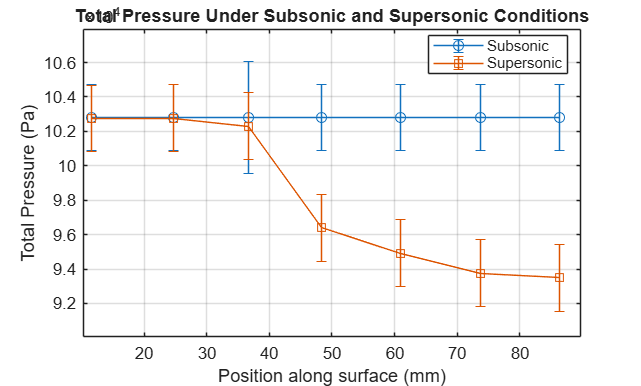




% FOR TOTAL PRESSURE, It is a bit different. 
% Total (Stagnation) Pressures for Ports 1 to 7 (Subsonic vs Supersonic).
% You want to get the static pressures at their respective ports. Do not
% use the code from part 1. 

v_port1 = (mean(gain*((port1(:,2) - averageOffset)))) +101300 ; %v0 corresponds to the port for that channel. We do not consider the other channels. 
v_port2 = (mean(gain*((port2(:,3) - averageOffset)))) + 101300;
v_port3 = (mean(gain*((port3(:,4) - averageOffset)))) + 101300;
v_port4 = (mean(gain*((port4(:,6) - averageOffset)))) + 101300;
v_port5 = (mean(gain*((port5(:,5) - averageOffset)))) + 101300;
v_port6 = (mean(gain*((port6(:,7) - averageOffset)))) + 101300;
v_port7 = (mean(gain*((port7(:,8) - averageOffset)))) + 101300;


v_port11 = (mean(gain*((port11(:,2) - averageOffset)))) + 101300 ; %v0 corresponds to the port for that channel. We do not consider the other channels. 
v_port12 = (mean(gain*((port12(:,3) - averageOffset)))) + 101300;
v_port13 = (mean(gain*((port13(:,4) - averageOffset)))) + 101300;
v_port14 = (mean(gain*((port14(:,6) - averageOffset)))) + 101300;
v_port15 = (mean(gain*((port15(:,5) - averageOffset)))) + 101300;
v_port16 = (mean(gain*((port16(:,7) - averageOffset)))) + 101300;
v_port17 = (mean(gain*((port17(:,8) - averageOffset)))) + 101300;

%The 11th column is where the stagnation pressure lies. 
tot_p_1_sub   = (mean(gain*((port1(:,13) - averageOffset)))) + 101300; 
tot_p_1_super = (mean(gain*((port11(:,13) - averageOffset))))+ 101300; 

tot_p_2_sub   = (mean(gain*((port2(:,13) - averageOffset))))+ 101300;
tot_p_2_super = (mean(gain*((port12(:,13) - averageOffset))))+ 101300;

tot_p_3_sub   = (mean(gain*((port3(:,13) - averageOffset)))) + 101300;
tot_p_3_super = (mean(gain*((port13(:,13) - averageOffset))))+ 101300;

tot_p_4_sub   = (mean(gain*((port4(:,13) - averageOffset)))) + 101300; 
tot_p_4_super = (mean(gain*((port14(:,13) - averageOffset))))+ 101300;
 
tot_p_5_sub   = (mean(gain*((port5(:,13) - averageOffset)))) + 101300;
tot_p_5_super =(mean(gain*((port15(:,13) - averageOffset))))+ 101300;

tot_p_6_sub   = (mean(gain*((port6(:,13) - averageOffset))))+ 101300;
tot_p_6_super =(mean(gain*((port16(:,13) - averageOffset))))+101300;

% Corrected from column 8 to column 12 to match the reference stagnation channel
tot_p_7_sub   = (mean(gain*((port7(:,13) - averageOffset))))  + 101300;
tot_p_7_super = (mean(gain*((port17(:,13) - averageOffset))))+ 101300;
v_ports_sub = [v_port1, v_port2, v_port3, v_port4, v_port5, v_port6, v_port7];
v_ports_super = [v_port11,v_port12, v_port13, v_port14, v_port15, v_port16, v_port17];

x_tot = [11.6, 24.7, 36.6, 48.3, 61.0, 73.7, 86.4]; % will help for indexing afterwards. 
tot_p_sub = [tot_p_1_sub, tot_p_2_sub, tot_p_3_sub, tot_p_4_sub, tot_p_5_sub, tot_p_6_sub, tot_p_7_sub]; 
tot_p_super = [tot_p_1_super, tot_p_2_super, tot_p_3_super, tot_p_4_super, tot_p_5_super, tot_p_6_super, tot_p_7_super];


% This is for error propagation for graphing purposes. 
tot_p_1_sub_e = gain*sqrt(((std(port1(:,13)./sqrt(7)).^2 + offset_e^2) +(std(port1(:,2)./sqrt(7)).^2)));

[numrow2,numcolm2] = size(port2(:,13));
tot_p_2_sub_e = gain*sqrt(((std(port2(:,13)./sqrt(7)).^2 + offset_e^2) + (std(port2(:,3)./sqrt(7)).^2)));
[numrow3,numcolm3] = size(port3(:,13));
tot_p_3_sub_e = gain*sqrt(((std(port3(:,13)./sqrt(7)).^2 + offset_e^2) + std((port3(:,4)./sqrt(7)).^2)));

[numrow4, numcolm4] = size(port4(:,13));
tot_p_4_sub_e = gain*sqrt((std(port4(:,13))./sqrt(7)).^2 + offset_e^2 +(std(port4(:,6))./sqrt(7)).^2);

[numrow5, numcolm5] = size(port5(:,13));
tot_p_5_sub_e = gain*sqrt((std(port5(:,13))./sqrt(7)).^2 + offset_e^2 + (std(port5(:,5))./sqrt(7)).^2);

[numrow6, numcolm6] = size(port6(:,13));
tot_p_6_sub_e = gain*sqrt((std(port6(:,13))./sqrt(7)).^2 + offset_e^2 + (std(port6(:,7))./sqrt(7)).^2);

[numrow7,numcolm7] = size(port7(:,13));
tot_p_7_sub_e = gain*sqrt(((std(port7(:,13))./sqrt(7)).^2 + offset_e^2) + (std(port6(:,8))./sqrt(7)).^2);

[numrow8,numcolm8] = size(port11(:,13));
tot_p_1_super_e = gain*sqrt(((std(port11(:,13))./sqrt(7)).^2 + offset_e^2) + (std(port6(:,2))./sqrt(7)).^2);

[numrow9, numcolm9] = size(port12(:,13));
tot_p_2_super_e = gain * sqrt((std(port12(:,13))/sqrt(7))^2 + offset_e^2 + (std(port6(:,3))/sqrt(7))^2);

[numrow10, numcolm10] = size(port13(:,13));
tot_p_3_super_e = gain * sqrt((std(port13(:,13))/sqrt(7))^2 + offset_e^2 + (std(port6(:,4))/sqrt(7))^2);

[numrow11, numcolm11] = size(port14(:,13));
tot_p_4_super_e = gain * sqrt((std(port14(:,13))/sqrt(7))^2 + offset_e^2 +(std(port6(:,6))/sqrt(7))^2);

[numrow12, numcolm12] = size(port15(:,13));
tot_p_5_super_e = gain * sqrt((std(port15(:,12))/sqrt(7))^2 + offset_e^2) + (std(port6(:,5))/sqrt(7))^2;

[numrow13, numcolm13] = size(port16(:,13));
tot_p_6_super_e = gain * sqrt((std(port16(:,12))/sqrt(7))^2 + offset_e^2 + (std(port6(:,7))/sqrt(7))^2);

[numrow14, numcolm14] = size(port17(:,13));
tot_p_7_super_e = gain * sqrt((std(port17(:,12))/sqrt(7))^2 + offset_e^2 + (std(port7(:,8))/sqrt(7))^2);

tot_p_sub_e   = [tot_p_1_sub_e, tot_p_2_sub_e, tot_p_3_sub_e, tot_p_4_sub_e, ...
    tot_p_5_sub_e, tot_p_6_sub_e, tot_p_7_sub_e];
tot_p_super_e = [tot_p_1_super_e, tot_p_2_super_e, tot_p_3_super_e, tot_p_4_super_e, ...
    tot_p_5_super_e, tot_p_6_super_e, tot_p_7_super_e];

figure;
errorbar(x_tot, tot_p_sub,   tot_p_sub_e,   '-o');
hold on;
errorbar(x_tot, tot_p_super, tot_p_super_e, '-s');
hold off;
xlabel('Position along surface (mm)');
ylabel('Total Pressure (Pa)');
title('Total Pressure Under Subsonic and Supersonic Conditions');
legend('Subsonic', 'Supersonic', 'Location', 'best');
grid on;

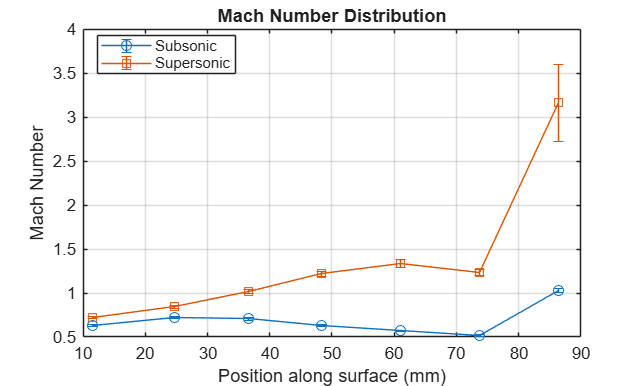

% Your experimental ratio: P_o2 (total pressure) / P_1 (static pressure at each port)
% Ensure these match your supersonic vectors (e.g., tot_p_super and v_supersonic)
idx = 1:numel(x_tot);                 % ports 1..7

static_sub   = v_ports_sub;          % static pressure at each total-pressure port
static_super = v_ports_super;

pressure_ratio_sub   = tot_p_sub ./ static_sub;
g = 1.4; 
M_subsonic = sqrt((((pressure_ratio_sub).^((g - 1)/g)) - 1)* (2/(g -1)));

% to get M_supersonic values, the values were obtained numerically through Desmos. 
x_throat = 33.6;   % mm, from your tunnel geometry
isSuper = x_tot > x_throat;
rayleigh = @(M) ((g+1)*M.^2/2).^(g/(g-1)) .* ...
    ((2*g/(g+1))*M.^2 - (g-1)/(g+1)).^(-1/(g-1));

Po2_P1 = tot_p_super ./ static_super;
ratio_M1 = rayleigh(1);   % ~1.893

M_supersonic = zeros(size(Po2_P1));
Po1_P1 = zeros(size(Po2_P1));

for i = 1:numel(Po2_P1)
    if isSuper(i) && Po2_P1(i) >= ratio_M1
        M_supersonic(i) = fzero(@(M) rayleigh(M) - Po2_P1(i), [1.0001, 5]);
    else
        if isSuper(i)
            warning('Port %d is past the throat but P02/P1 = %.3f < %.3f (flow not supersonic here?)', ...
                i, Po2_P1(i), ratio_M1);
        end
        M_supersonic(i) = sqrt((Po2_P1(i)^((g-1)/g) - 1) * 2/(g-1));
    end
    Po1_P1(i) = (1 + (g-1)/2*M_supersonic(i)^2)^(g/(g-1));
end
% ---------------- Mach numbers ----------------


% these values come from using the equations and plotting them on desmos
% because they are difficult to rearrange using MATLAB. You use the Mach
% number to find the Po1/P1 ratio to plot instead. 


stat_p_sub_e_fM   = [stat_p_1_sub_e, stat_p_2_sub_e, stat_p_3_sub_e, stat_p_4_sub_e, ...
    stat_p_5_sub_e, stat_p_6_sub_e, stat_p_7_sub_e];

stat_p_super_e_fM = [stat_p_1_super_e, stat_p_2_super_e, stat_p_3_super_e, stat_p_4_super_e, ...
    stat_p_5_super_e, stat_p_6_super_e, stat_p_7_super_e];

M_sub_e = M_subsonic .* sqrt((stat_p_sub_e_fM ./ static_sub).^2 + (tot_p_sub_e ./ tot_p_sub).^2) / 2;
M_super_e = M_supersonic .* sqrt((stat_p_super_e_fM ./ static_super).^2 + (tot_p_super_e ./ tot_p_super).^2) / 2;

Po1_P1 = (1 + (g-1)/2*M_supersonic.^2).^(g/(g-1));
figure;
errorbar(x_tot, M_subsonic, M_sub_e, '-o');
hold on;
errorbar(x_tot, M_supersonic, M_super_e,  '-s');
xlabel('Position along surface (mm)');
ylabel('Mach Number');
title('Mach Number Distribution');
legend('Subsonic', 'Supersonic', 'Location', 'best');
grid on;


pressure_ratio_sub  = static_sub ./ tot_p_sub

pressure_ratio_sub =     0.7671    0.7085    0.7179    0.7640    0.8023    0.8327    0.5100


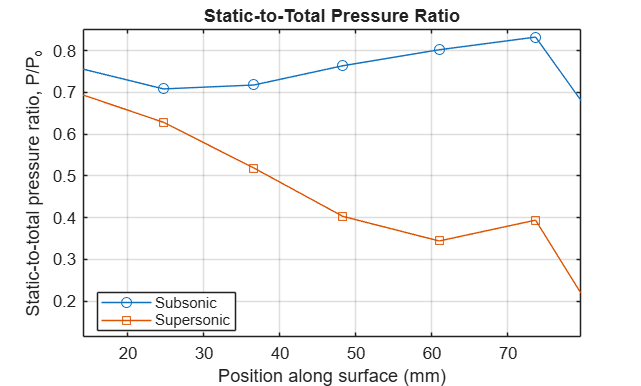

figure;
plot(x_tot, pressure_ratio_sub, '-o', x_tot, 1./Po1_P1, '-s');
xlabel('Position along surface (mm)');
ylabel('Static-to-total pressure ratio, P/P_o');
legend('Subsonic', 'Supersonic', 'Location', 'best');
title('Static-to-Total Pressure Ratio');
grid on;